addpath("matlab_pure");
addpath("mex_files");

`Welcome to tutorial 2! Here we will go over how to set-up the PyCauchyEstimator and PySlidingWindowManager classes to estimate the state of a nonlinear dynamic system. If you have not already taken a look over the tutorial lti_systems.ipynb, now would be a very good time to do so. This tutorial introduced both these classes, and some conventions that will likely be glossed over in this tutorial. `

`Setting up the Cauchy Estimator for nonlinear systems is just as straight forward as running an Extended Kalman filter. Lets take a simple 2-state nonlinear system and set-up the EKF for it. Then, we will go ahead and set-up the Cauchy Estimator. In the spirit of historically significant but simple systems, lets consider a simple swinging pendulum example, illustrated below:`

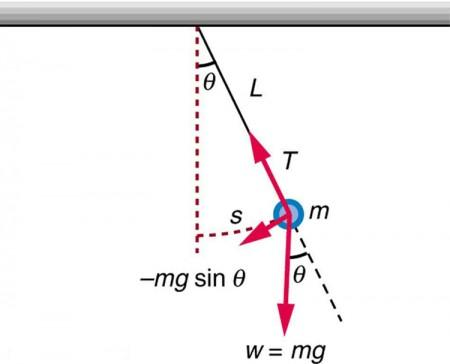

`The pendulum is a nonlinear system with two states of interest: the angle $``\theta$`` from its stationary vertical position, and its angular rate $``\``dot``{\theta}$``. Pulling out our old high school physics textbook, the equation of motion (EOM) for angular acceleration $``\``ddot``{\theta}$`` is given as`

`\begin{equation}`

`    \ddot{\theta} = -\frac{g}{L} \text{sin}(\theta) - c\dot{\theta} + w`

`\end{equation}`

`where $``g$`` is the acceleration due to gravity, $``L$`` is the length of the pendulum, c is a damping factor which will reduce the amplitude of the penduulum swing, and w is a zero mean process noise with power spectral density $``W$``, which could either model the imperfect identification of the $``c$`` parameter, or possibly some squeakiness on the hinge of the pendulum. We can simulate this system nicely using really any integration method with the above EOM. Here, we'll use an RK4 integrator, since its already baked into the cauchy_estimator module. Let's go ahead and simulate the pendulum motion of $``\theta$`` and $``\dot\theta$`` starting at an angle of $``45``$`` degrees:`

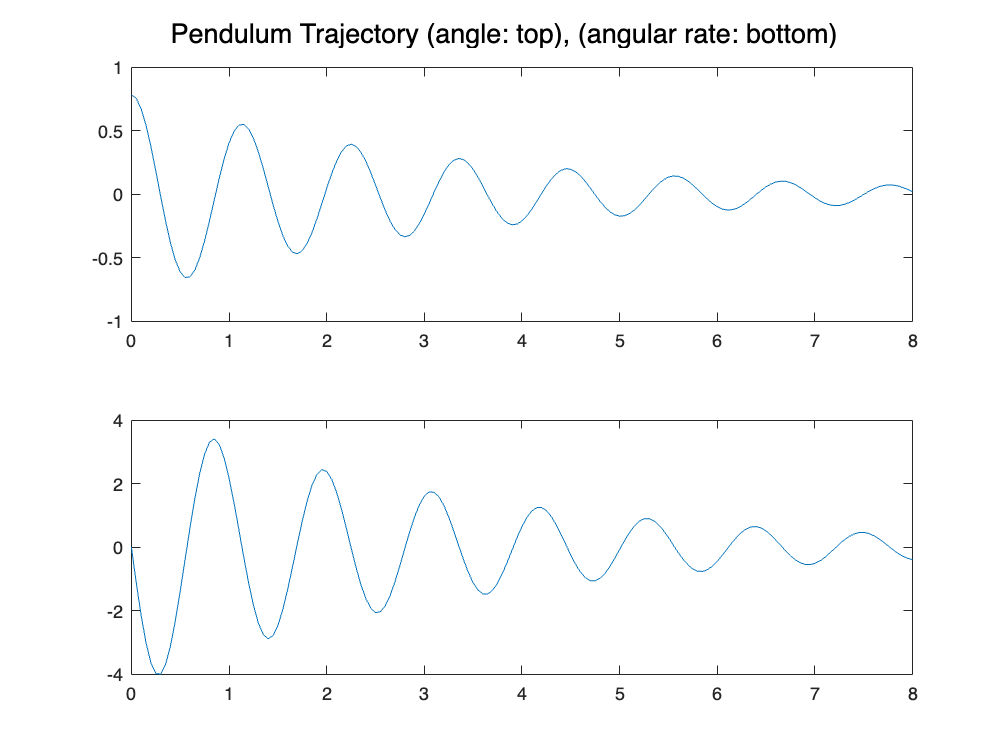

% PendulumParams
global pend; % Lets just make a simple globally viewable object to get ahold of these parameters when we want them
pend = struct(...
    'L', 0.3, ...        % meters
    'g', 9.81, ...       % meters / second^2
    'c', 0.6, ...        % 1/seconds (damping)
    'w_PSD', 0.01, ...   % power spectral density of continuous-time process noise
    'dt', 0.05 ...       % integration step time
);

% The ODE
function dx_dt = pend_ode(x)
    global pend;
    dx_dt = zeros(2, 1);
    dx_dt(1) = x(2);
    dx_dt(2) = -pend.g / pend.L * sin(x(1)) - pend.c * x(2);
end

% Nonlinear transition model from t_k to t_k+1...ie: dt
function x_new = nonlin_transition_model(x)
    global pend;
    x_new = runge_kutta4(@pend_ode, x, pend.dt);
end

theta_vec0 = [pi/4; 0]; % initial angle of 45 degrees at 0 radians/sec
theta_k = theta_vec0;
thetas = theta_k';
propagations = 160;
for k = 1:propagations
    theta_k = nonlin_transition_model(theta_k);
    thetas = [thetas; theta_k'];
end
Ts = ((0:propagations) * pend.dt)';
figure;
sgtitle('Pendulum Trajectory (angle: top), (angular rate: bottom)');
subplot(2, 1, 1);
plot(Ts, thetas(:, 1));
subplot(2, 1, 2);
plot(Ts, thetas(:, 2));

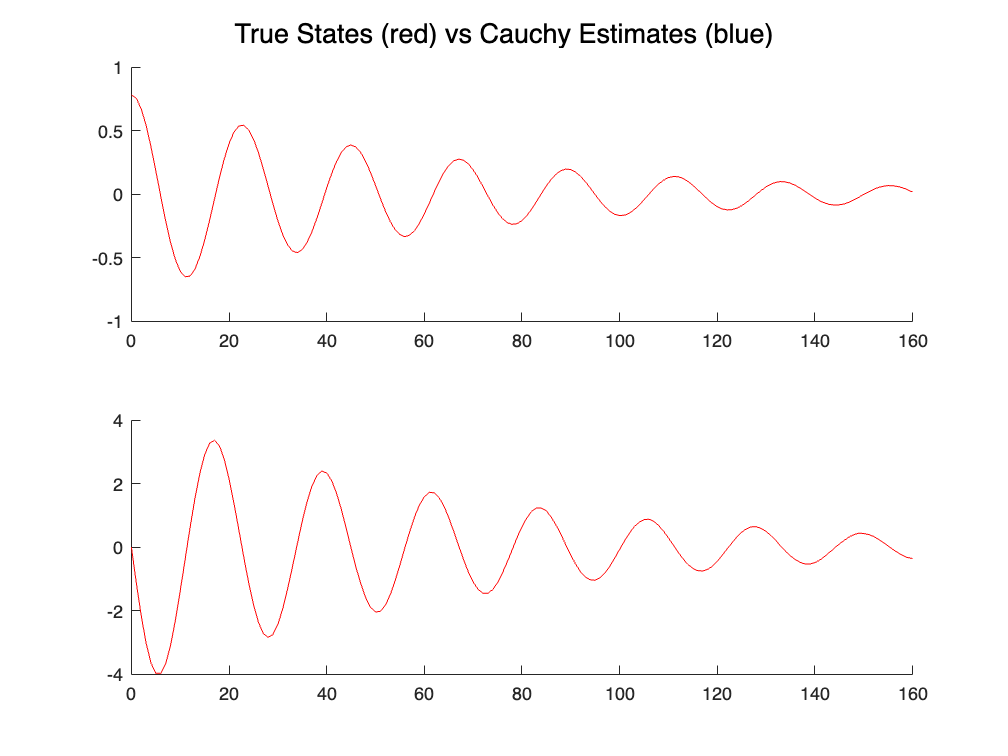

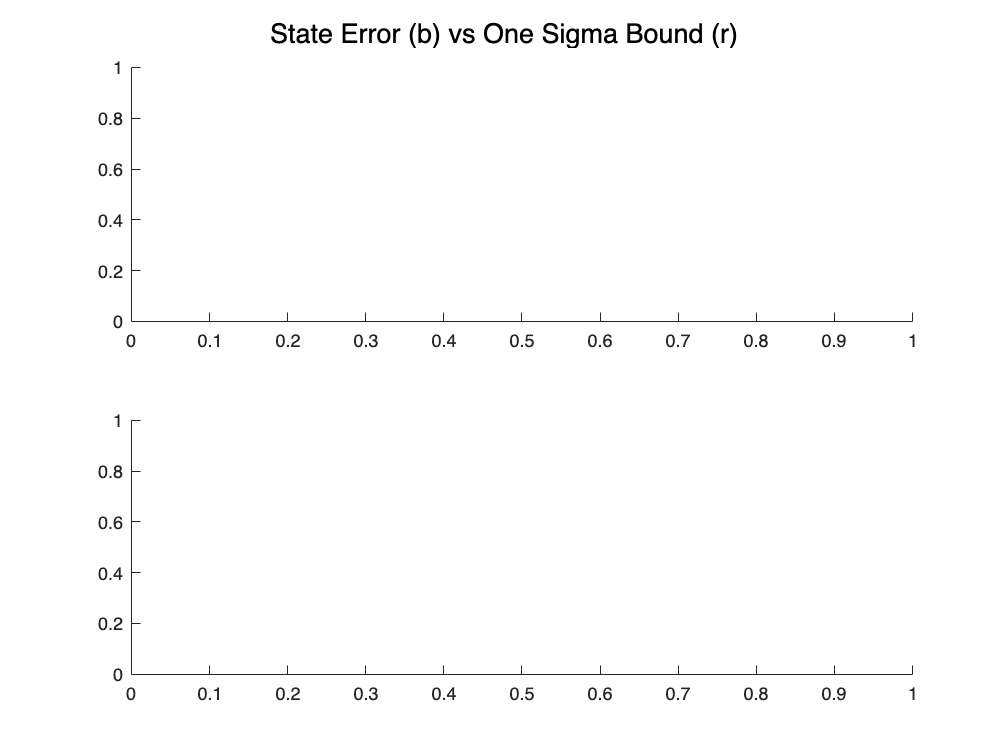

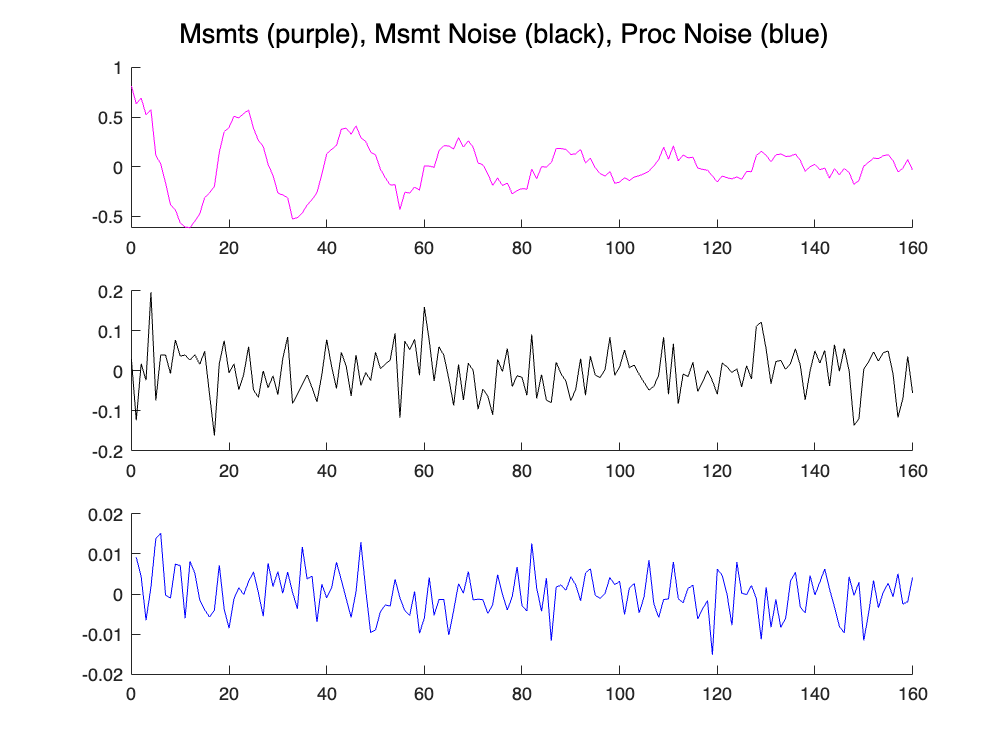

% Creating the dynamic simulation
V = 0.003; % measurement noise on theta
H = [1.0, 0.0]; % meausrement model
xk = theta_vec0;
xs = xk'; % State vector history
ws = [];   % Process noise history
vs = sqrt(V(1)) * randn(); % Measurement noise history
zs = H * xk + vs(1); % Measurement history
propagations = 160;
for k = 1:propagations
    wk = pend.dt * sqrt(pend.w_PSD) * randn();
    xk(2) = xk(2) + wk;
    xk = nonlin_transition_model(xk);
    xs = [xs; xk'];
    ws = [ws; wk];
    vk = sqrt(V(1)) * randn();
    zk = H * xk + vk;
    vs = [vs; vk];
    zs = [zs; zk];
end
plot_simulation_history([], {xs,zs,ws,vs}, [])

% Now we have our simulation data!